# Exercise 2: Linear Programming

Finn Vehlhaber and Leonardo Pedroso

**Run the sections one by one by clicking into the respective code window and hitting "Run Section". Sentences highlighted in bold give instructions on how to complete the given code. Code lines like this need to be completed by you:**

% ----- complete code here
% (incomplete code here)
% -----

Clean up script

clear; close all; clc

### Exercise 2: Linear Programming

Consider Exercise 2 in the handout. 

**Complete the variables, constraints, and objective in the code given below**

yalmip('clear');

% optimization variables
% ----- complete code here
x1 = sdpvar(1,1);
x2 = sdpvar(1,1);
% -----

% Define constraints
% ----- complete code here
constraints = [4*x1 + 5*x2 <= 120; 
               5*x1 + 3*x2 <= 60;
               2*x2 <= 30;
               x1 >= 0;
               x2 >= 0];
% -----

% Define objective
% ----- complete code here
objective = -(5*x1+8*x2);
% -----

% Solve problem
opts = sdpsettings('solver','linprog','verbose',2);
optimize(constraints,objective,opts);

MOSEK Version 10.1.21 (Build date: 2023-12-1 10:48:53)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: MACOSX/aarch64

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 5               
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 2               
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Optimizer terminated. Time: 0.00    


Interior-point solution summary
  Problem status  : PRIMAL_AND_DUAL_FEASIBLE
  Solution status : OPTIMAL
  Primal.  obj: -1.3500000000e+02   nrm: 9e+01    Viol.  con: 4e-09    var: 0e+00  
  Dual.    obj: -1.3500000000e+02   nrm: 2e+00    Viol.  con: 0e+00    var: 3e-10  

Basic solution summary
  Problem status  : PRIMAL_AND_DUAL_FEASIBLE
  Solu

[value(x1);value(x2)]

ans =     3.0000
   15.0000


Plot

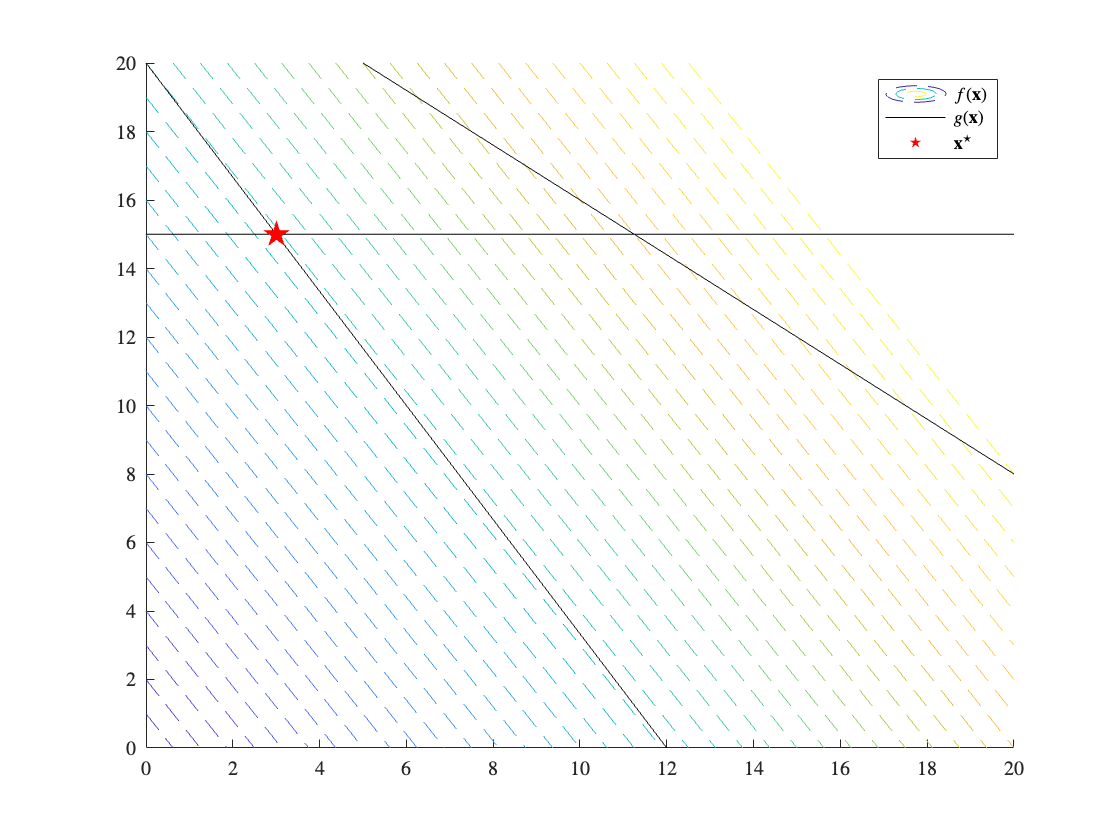

x1vector = 0:1:20;
x2vector = 0:1:20;
figure;
hold on
% objective function
contour(x1vector,x2vector,5*x1vector'*ones(1,21) + 8*ones(21,1) * x2vector,0:5:200,'--','DisplayName','$f(\mathbf{x})$')
% constraints
plot(x1vector,(60 - 5*x1vector)/3,'k','DisplayName','$g(\mathbf{x})$');
plot(x1vector,(120 - 4*x1vector)/5,'k','HandleVisibility','off');
plot([0 20],[15 15],'k','HandleVisibility','off');
scatter(value(x1),value(x2),200,'r','filled','pentagram','DisplayName','$\mathbf{x}^\star$')
hold off
xlim([0 20])
ylim([0 20])
legend('Interpreter','latex','Location','northeast')
set(gca,'ticklabelinterpreter','latex')